clear all
load fisheriris


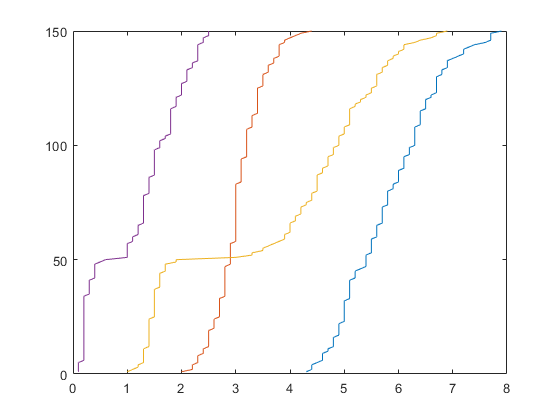

rng('default')
% rand(2,2);
[C,ia,ic] = unique(species);

y = [ic==1 ic==2 ic==3];
indexez= randperm(150);

plot(sort(meas()),(1:150))

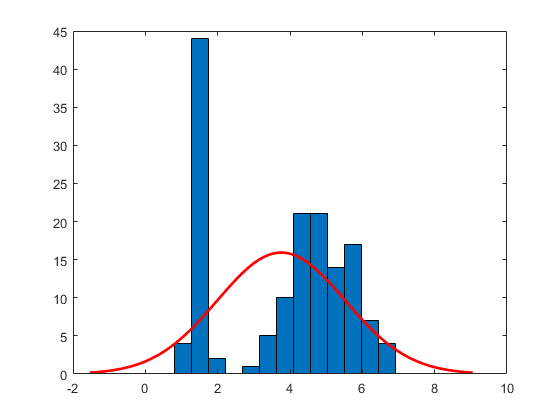

histfit((meas(:,3)))

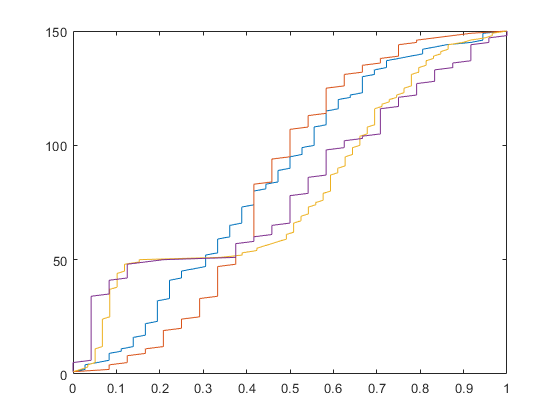


input = normalize(meas(indexez,:),'range');
plot(sort((input)), 1:150)

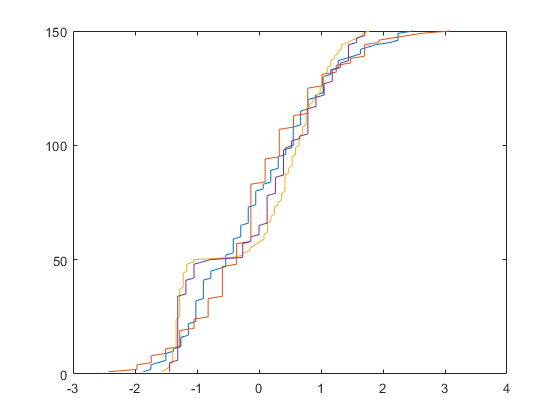


output = y(indexez,:);

input2 = normalize(meas(indexez,:));

g = (1 + exp(-1 * input2)) .^ -1;

plot(sort((input2)), 1:150)

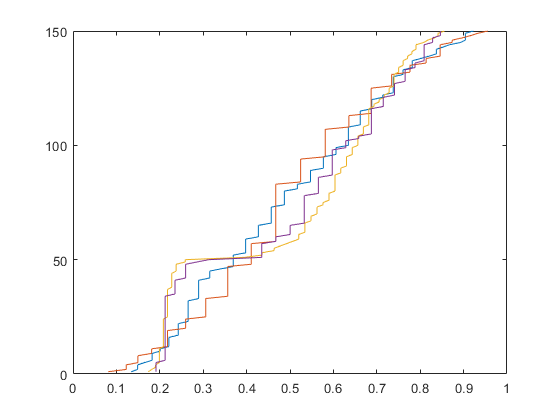

plot(sort((g)), 1:150)


testinput = g((end-49):end,:);
testoutput = output((end-49):end,:);

batchsize = 100;

in = g(1:batchsize,:);
out = output(1:batchsize,:);

n = 1;


knots = 6

knots = 6

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);

B=[];
C=[];


% Vandermonde ----------

for i = 1:batchsize
    
    index_a(i)= floor((in(i,1)*knots+(10*knots*eps)))+1;
    index_b(i)= floor((in(i,2)*knots+(10*knots*eps)))+1;
    index_c(i)= floor((in(i,3)*knots+(10*knots*eps)))+1;
    index_d(i)= floor((in(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(in(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(in(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(in(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(in(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,index_a(i):index_a(i)+2) = Ntemp_a;
    N_b(i,index_b(i):index_b(i)+2) = Ntemp_b;
    N_c(i,index_c(i):index_c(i)+2) = Ntemp_c;
    N_d(i,index_d(i):index_d(i)+2) = Ntemp_d;
  
    N_T{i} = [N_a(i,:); N_b(i,:); N_c(i,:); N_d(i,:)];
    
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
B(i,:)=f(:)';
    
% a=in(i,1).^[0:n];  % a = a/norm(a);
% b=in(i,2).^[0:n];  % b = b/norm(b);
% c=in(i,3).^[0:n];  % c = c/norm(c);
% d=in(i,4).^[0:n];  % d = d/norm(d);
% 
% f= outproduct(a,b,c,d);
% B(i,:)=f(:)';
end
% ----------- ----------


training logistic sigmoid

w = randn([(knots+2)^4 3])/100;

alpha=10;

tic
for i= 1:1
z1 = B*w;
expp = exp(z1-max(z1,[],1));
p1 = expp./sum(expp,2);
sum(p1,2);
% p1 = max(min(p1, 0.95),0.05);
d1 = p1-out;

tempo=(z1-alpha*d1);

w = pinv(B)*(tempo);
end
toc

Elapsed time is 0.072751 seconds.



% -------------------------------------

Theta=zeros(size(B,2),3)

Theta =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


Pcov =eye(size(B,2))*100

Pcov =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   100     0     0     0     0     0     0     0     0     0     0     0


tic

for epoch=1:1

for kk=1:100
    
Phi = B(kk,:);

PhiP = Phi * Pcov;

Pcov = Pcov - (PhiP'*PhiP)/(1+PhiP*Phi');

% Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsil = tempo(kk,:) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsil;

end
end
toc

Elapsed time is 5.754350 seconds.


% -----------------------------------



tol=10^-10

tol = 1.0000e-10

lambda=0.5

lambda = 0.5000


d=4

d = 4

n=knots+2

n = 8

l=3

l = 3


sigmas= [10^5]

sigmas = 100000


PcovT=initP(sigmas,n,d)

PcovT = struct with fields:
       n: [4×5 double]
    core: {[8×8 double]  [8×8 double]  [8×8 double]  [8×8 double]}


PcovT.n

ans =      1     8     8     1     1
     1     8     8     1     1
     1     8     8     1     1
     1     8     8     1     1


ttcontractkim(PcovT)

ans =       100000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0      100000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0         


XT=initm(l,n,d)

XT = struct with fields:
       n: [4×4 double]
    core: {[1×8×3 double]  [0 0 0 0 0 0 0 0]  [0 0 0 0 0 0 0 0]  [0 0 0 0 0 0 0 0]}


XT.core

ans = 1×4 cell array
    {1×8×3 double}    {1×8 double}    {1×8 double}    {1×8 double}


XT.n

ans =      1     8     3     1
     1     8     1     1
     1     8     1     1
     1     8     1     1


ttcontractkim(XT)

ans =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


% rgf = K.core{1}
% 
% K.n(1,3)=3
% 
% rgf =reshape(rgf(:)*[1 2 3], K.n(1,[1 2 4 3]))
% rgf = permute(rgf,[1 2 4 3])
% sum(rgf(:,:,3,:),'all')

% 
% onzie = ones(5,1)



% 
% G=XT
% C = N_T{1};
% 
% % f = contractX(G,C)
% 
% d= size(G.n,1);
% 
% Gsize = G.n(:,[1 3 end]);
% 
% for i = 1:d
% Gt.core{i} = squeeze(reshape(C(i,:)*unfold(G.core{i},2), Gsize(i,:)));
% end
% 
% f = Gt.core{1};
% 
% if isrow(f)
%     f=f'
% end
% 
% 
% 
% for j = 2:d
% f = f*(Gt.core{j})
% % f = reshape(f,1, []) *squeeze(Gt.core{j});
% end
% f



 epsil=zeros(100,3)

epsil =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



lambda=0.2

lambda = 0.2000


mxepoch=8

mxepoch = 8

% ------------------------------------
for epochs=1:mxepoch
    
randix= randperm(100);    
    
    if epochs>1
    lambda=0.9+epochs/(10*mxepoch)
    end
    
for kk=1:100

    if mod(kk,10)==0
        disp(kk)
    end
    
Phi = N_T{randix(kk)};
f = contractX(XT,Phi);

epsil(randix(kk),:) = tempo((randix(kk)),:) - f';

Pc = contractPC(PcovT,Phi,0);
% ttcontractkim(Pc);

cP = contractPC(PcovT,Phi,1);
% ttcontractkim(cP);

cPc = contractCPC(Pc,Phi);

c=squareTN(Pc,cP);
% ttcontractkim(c);

for j=1:size(c.n,1)
c.core{j} = reshape(c.core{j},c.n(j,:));
end

c.core{1} = c.core{1}*(-1/(lambda+cPc));
% ttcontractkim(c);

PcovT = addTN(c,PcovT);

if mod(kk,1)==0
PcovT = roundTN(PcovT,0.01);
end

PcovT = reshapeP(PcovT);
PcovT.core{end}= PcovT.core{end}*lambda;

% ttcontractkim(PcovT)

K = contractPC(PcovT,Phi,0);

K.n(1,3)=l;

K.core{1}=permute(reshape(K.core{1}(:)*epsil(kk,:), K.n(1,[1 2 4 3])),[1 2 4 3]);

% K.core{1}= K.core{1}*epsil(kk);
ttcontractkim(K);

XT = addTN(XT,K);

if mod(kk,1)==0
XT = roundTN(XT,tol);
end

XT.core{1} = reshape(XT.core{1},XT.n(1,:));

end


end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



lambda = 0.9250

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



lambda = 0.9375

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



lambda = 0.9500

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



lambda = 0.9625

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



lambda = 0.9750

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



lambda = 0.9875

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



lambda = 1

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100



% -----------------------------------


test =ttcontractkim(XT);




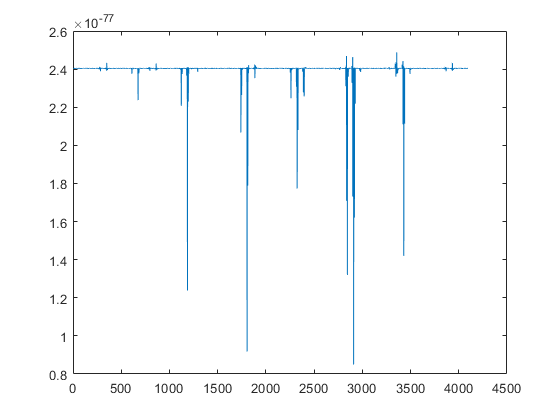


plot(diag(ttcontractkim(PcovT)))

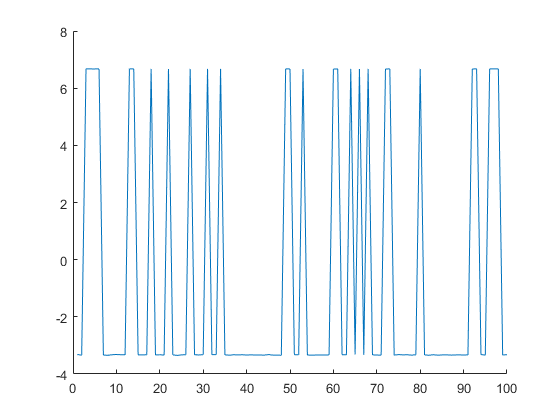


figure;
hold on
% plot(epsilo)
plot(epsil(:,1))
hold off

testi = 1

testi = 1

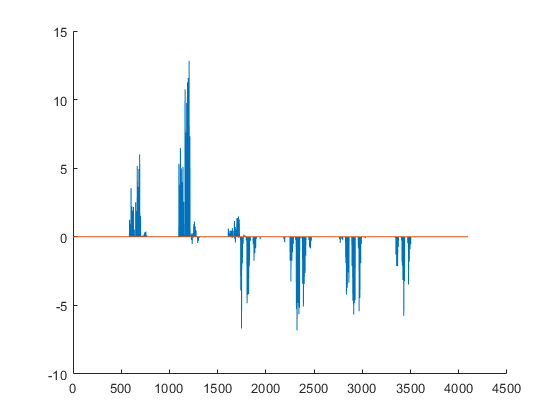


figure;
hold on
plot(Theta(:,testi))
% plot(w(:,testi))
plot(test(:,testi))

hold off

% plot(w(:,testi)-Theta(:,testi))

sum((w(:,testi))==0)

ans = 3100


sum(abs(sign(test(:,testi))-sign(Theta(:,testi))))

ans = 4077


w=Theta

w =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


w=test

w = 	1.0e+-3 *

    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000


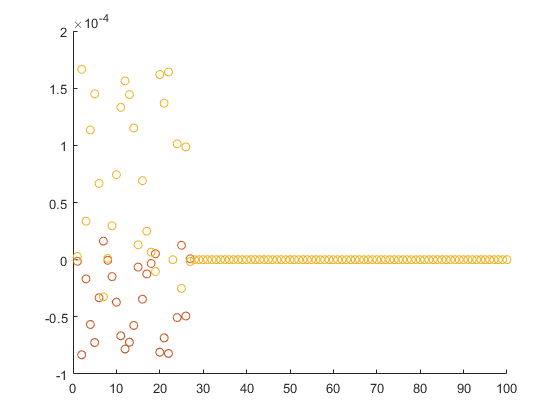


z1 = B*w;
expp = exp(z1-max(z1,[],1));
p1 = expp./sum(expp,2);

zy = B*w;
ay = p1;

zet=[];
zet(indexez(1:batchsize),:)=zy(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

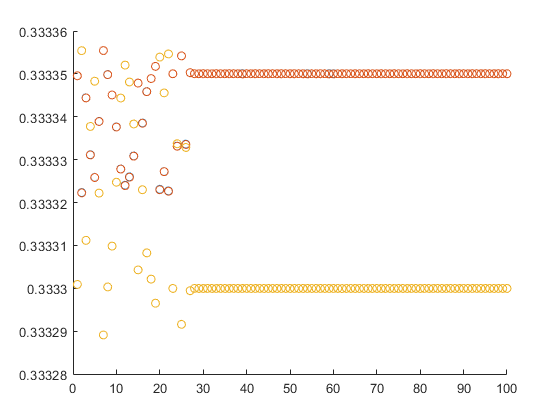


zet=[];
zet(indexez(1:batchsize),:)=ay(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

% TEST set


% Vandermonde ----------test
Btest=[];
N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);
for i = 1:50

     testindex_a(i)= floor((testinput(i,1)*knots+(10*knots*eps)))+1;
     testindex_b(i)= floor((testinput(i,2)*knots+(10*knots*eps)))+1;
     testindex_c(i)= floor((testinput(i,3)*knots+(10*knots*eps)))+1;
     testindex_d(i)= floor((testinput(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(testinput(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(testinput(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(testinput(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(testinput(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,testindex_a(i):testindex_a(i)+2) = Ntemp_a;
    N_b(i,testindex_b(i):testindex_b(i)+2) = Ntemp_b;
    N_c(i,testindex_c(i):testindex_c(i)+2) = Ntemp_c;
    N_d(i,testindex_d(i):testindex_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
Btest(i,:)=f(:)';

end


zytest = Btest*w;

resizen = size(w);

wtensor = reshape(w,[(knots+2)*[1 1 1 1] 3]);
[G, rk] = ttsvd(wtensor,0.000001)

G = 5×1 cell array
    {1×8×3 double}
    {3×8×2 double}
    {2×8   double}
    {1×8   double}
    {1×3   double}


rk =      1
     3
     2
     1
     1



suz=0;
for k=1:length(G)
    suz = suz + numel(G{k});
end

% recon = tcontract(G);

% zytest = Btest*reshape(recon,resizen);

exppy = exp(zytest-max(zytest,[],2));
pytest = exppy./sum(exppy,2);

[Mxx, I] = max(pytest,[],2); 

misclassif = ~(I==ic(indexez(101:150)));
sum(abs(misclassif))/50

ans = 0.7800

sum(abs(pytest-testoutput), 'all')/(150)

ans = 0.4444


C = confusionmat(I,ic(indexez((end-49):end)))

C =      0     1     3
     9     5     4
    14     8     6


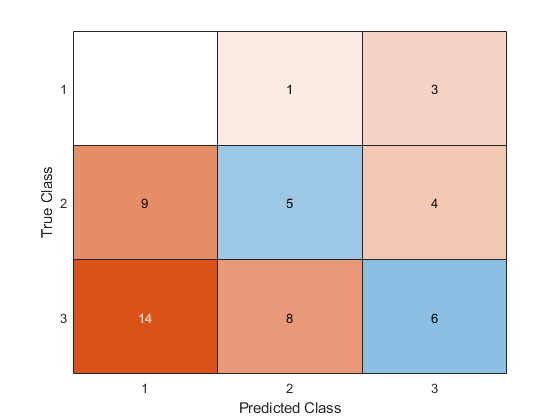

confusionchart(C);

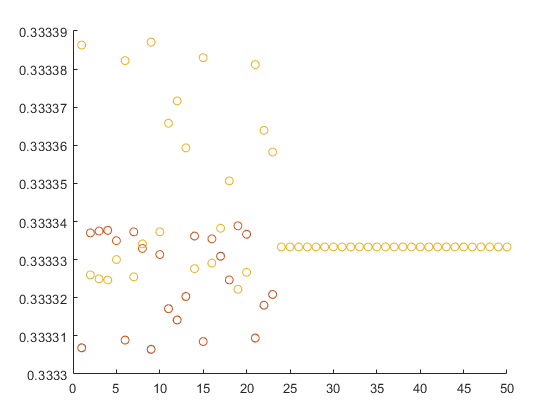


% scatter(1:50,misclassif);
figure;
zet=[];
zet(indexez((end-49):end),:)=pytest(1:end,:);
zet = zet(any(zet,2),:);

hold on
scatter(1:50,zet(:,1))
scatter(1:50,zet(:,2))
scatter(1:50,zet(:,3))
hold off



% rataa = norm(y-output)/norm(output)



wplot = reshape(w(:,1),(knots+2)*[1 1 1 1])

wplot = wplot(:,:,1,1) =

   1.0e-29 *

    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0001    0.0031    0.0378    0.0365    0.0004   -0.0000
   -0.0000   -0.0000    0.0001    0.0039    0.0883    0.1070    0.0013   -0.0000
    0.0000   -0.0000   -0.0002   -0.0003    0.0050    0.0077    0.0001   -0.0000
    0.0000   -0.0000    0.0000    0.0002   -0.0000    0.0001    0.0000   -0.0000
   -0.0000    0.0000    0.0000    0.0002   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000


wplot(:,:,2,1) =

   1.0e-19 *

    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000    0.0269    0.2024    0.1016    0.0012    0.0000
    0.0000   -0.0000   -0.0000    0.0398    0.3598    0.2459    0.0029    0.0000
    0.0000   -0.0000   -0.0000    0

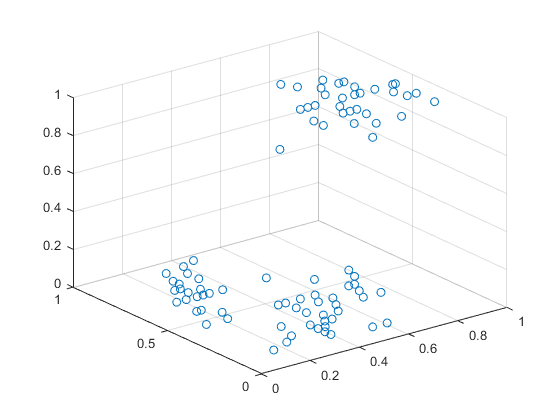


% surf(1:knots+1,1:knots+2,wplot(:,:,1,1))
% surf(input(:,1),input(:,2),double(rehape(y(:,1), []))

xx=in(:,1);
yy=in(:,2);
zz=double((out(:,3)));
scatter3(xx,yy,zz);

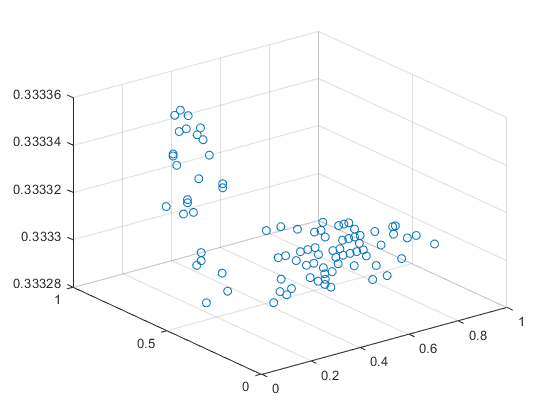


zz=double((output(:,3)));
zz=p1(:,3);

% zz=input(:,3)
% plot3(xx,yy,zz,'.-')
scatter3(xx,yy,zz);

% ii=1
% for re = logspace(-10,-0.5)
% [G, rk] = ttsvd(wplot,re)
% suz=0
% for k=1:4
%     suz = suz + numel(G{k});
% end
% 
% numberelements = numel(wplot)
% 
% numberelements/suz
% recon = tcontract(G);
% 
% 
% ploto(ii) = sum(abs(recon-wplot),'all')/numberelements
% 
% plotosuz(ii)=suz
% ii=ii+1;
% end
% 
% plot(ploto)
% plot(plotosuz)